# HAMR-6 SE(2) locomotion study

## 3D reconstruction of trajectory and kinematics

The goal of this section is to take the properties of HAMR reconstruct it in 3D and add the trajectory of the robot to it. Here's a marked up top view of HAMR-6 and that will be the subject of 3D reconstruction study. **All units are in mm.**

### Respecting form-factor symmetry

In this subsection, we shall use our bounding box measurements and respect the symmetry of the design. This would mean, as shown in the top-view, the bounding boxes shall have equal opposing sides.

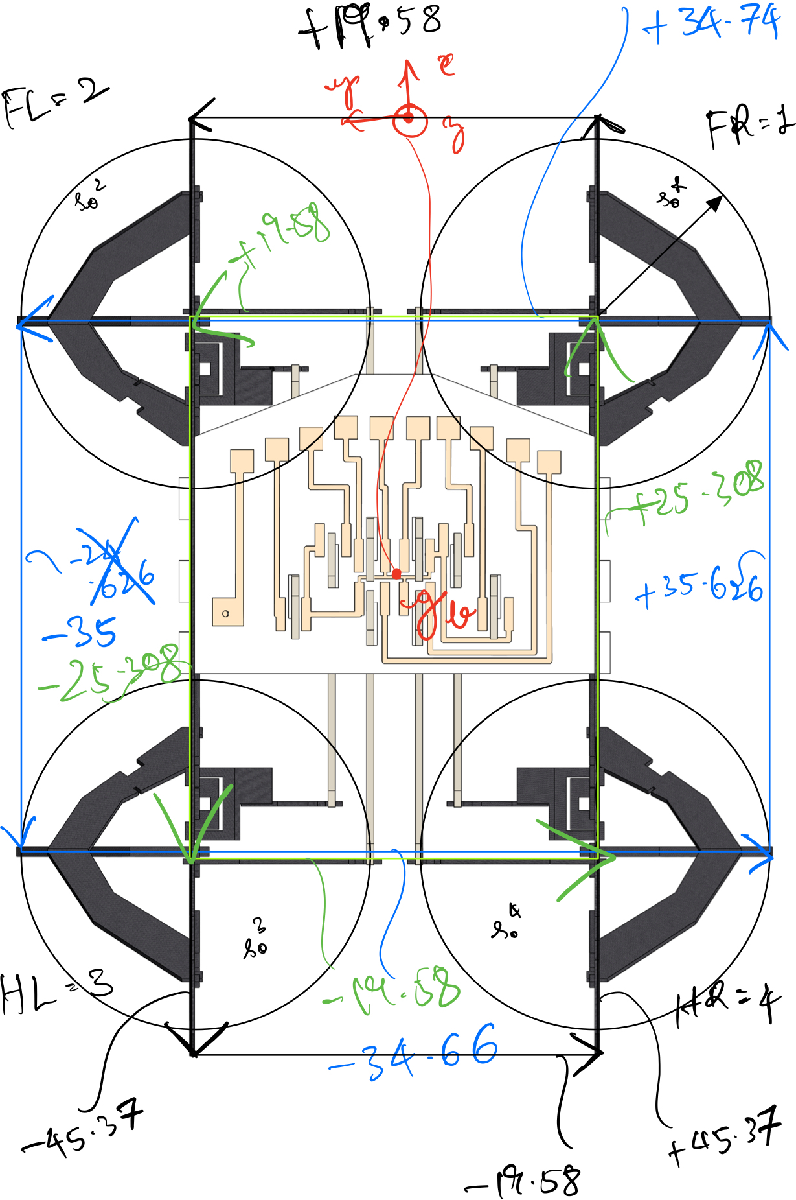

There and 3 bounding boxes above-- the green one connects the bases of each spherical five-bar transmission (SFB), the blue one connects the feet-tips, and the black one connects the tips of the body excluding the legs. These boxes are at different levels, and hence we need to handle that to get the right 3D reconstruction. Hence, these bounding boxes are defined as a set of cyclic vectors forming a closed shape (boxes in the quadrupedal case)-- the vectors are defined in a global rest frame that is aligned with the body frame before the motion begins. Assume the initial point of the first vector (tail) to be the origin for this set of vectors. We shall exploit the fact that all the these bounding boxes are centered around the body frame of the robot. NOTE: THE BOXES ARE AT DIFFERENT Z-LEVELS. This must be accounted for when doing the transformations.

Let's first round off all quantities to 3 significant digits instead of 4 significant digit measurement.

% add utilities function toe the path
addpath 'Data'\ 'Utility Functions'\;

% foot bounds ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
foot_bound = [[0, 34.74, 0]; [-35, 0, 0]; [0, -34.66, 0]; [35.626, 0, 0]]

foot_bound =          0   34.7400         0
  -35.0000         0         0
         0  -34.6600         0
   35.6260         0         0


foot_bound = boundboxmean(foot_bound, true) % true because it is designed to be a square

foot_bound =      0    35     0
   -35     0     0
     0   -35     0
    35     0     0


% hip bounds ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
hip_bound = [[0, 19.58, 0]; [-25.308, 0, 0]; [0, -19.58, 0]; [25.308, 0, 0]]

hip_bound =          0   19.5800         0
  -25.3080         0         0
         0  -19.5800         0
   25.3080         0         0


hip_bound = boundboxmean(hip_bound, false)

hip_bound =          0   19.6000         0
  -25.3000         0         0
         0  -19.6000         0
   25.3000         0         0


% body w/o leg bounds ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% there's a top and a bottom version for this bounding box and this will be addressed in the next section.
bodywoleg_bound = [[0, 19.58, 0]; [-45.37, 0, 0]; [0, -19.58, 0]; [45.37, 0, 0]]

bodywoleg_bound =          0   19.5800         0
  -45.3700         0         0
         0  -19.5800         0
   45.3700         0         0


bodywoleg_bound = boundboxmean(bodywoleg_bound, false)

bodywoleg_bound =          0   19.6000         0
  -45.4000         0         0
         0  -19.6000         0
   45.4000         0         0


### Translational transformations to body center

Now, let's compute the transforms from the body frame to the frames of interest-- we shall break down transformations into translations and rotations. Here's an isometric view of the 3D reconstruction of the robot we need and also the z change between various bounding boxes.

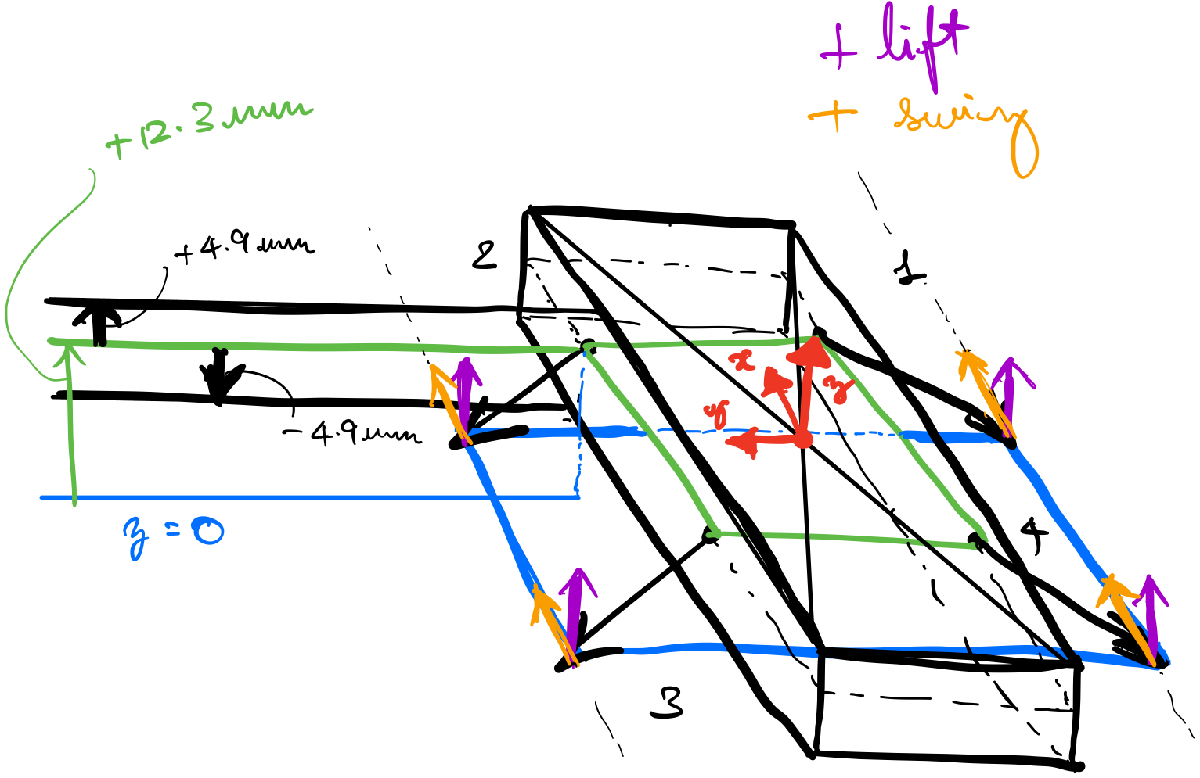

% z-change in HAMR6 with markers on (body center in the middle of the top plate in 2017 Ben Goldberg's: 10.1109/IROS.2017.8206249)
z_body2hipbox = [0, 0, -4.19];
z_body2bodyboundboxT = [0, 0, 0]; % top body bound box is at the body frame level
z_body2bodyboundboxB = [0, 0, -4.19*2];

% find the location of frame 1b hip-frame from the center of the robot-- translational sub-group of SE3
%%%%%%%%%% just h denotes SE2 transformations: ht translations, hR rotations
%%%%%%%%%% h3 denotes SE3 transformations: ht3 translations, hR3 rotations
ht3_b__hip = boundbox2ht3transform(hip_bound) + repmat(z_body2hipbox, [size(hip_bound, 1), 1]); % repeat over rows
ht3_b__1b = ht3_b__hip(1, :);
ht3_b__2b = ht3_b__hip(2, :);
ht3_b__3b = ht3_b__hip(3, :);
ht3_b__4b = ht3_b__hip(4, :);

% find the location of the top and bottom bounding boxes
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TOP
ht3_b__bboundT = boundbox2ht3transform(bodywoleg_bound)+ repmat(z_body2bodyboundboxT, [size(bodywoleg_bound, 1), 1]);
ht3_b__1cT = ht3_b__bboundT(1, :);
ht3_b__2cT = ht3_b__bboundT(2, :);
ht3_b__3cT = ht3_b__bboundT(3, :);
ht3_b__4cT = ht3_b__bboundT(4, :);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BOT
ht3_b__bboundB = boundbox2ht3transform(bodywoleg_bound)+ repmat(z_body2bodyboundboxB, [size(bodywoleg_bound, 1), 1]);
ht3_b__1cB = ht3_b__bboundB(1, :);
ht3_b__2cB = ht3_b__bboundB(2, :);
ht3_b__3cB = ht3_b__bboundB(3, :);
ht3_b__4cB = ht3_b__bboundB(4, :);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% JOIN (add links to join the top and bottom sides)
ht3_b__bboundB2T = ht3_b__bboundT - ht3_b__bboundB;

Let's plot what we have so far and visualize it from a few different view points.

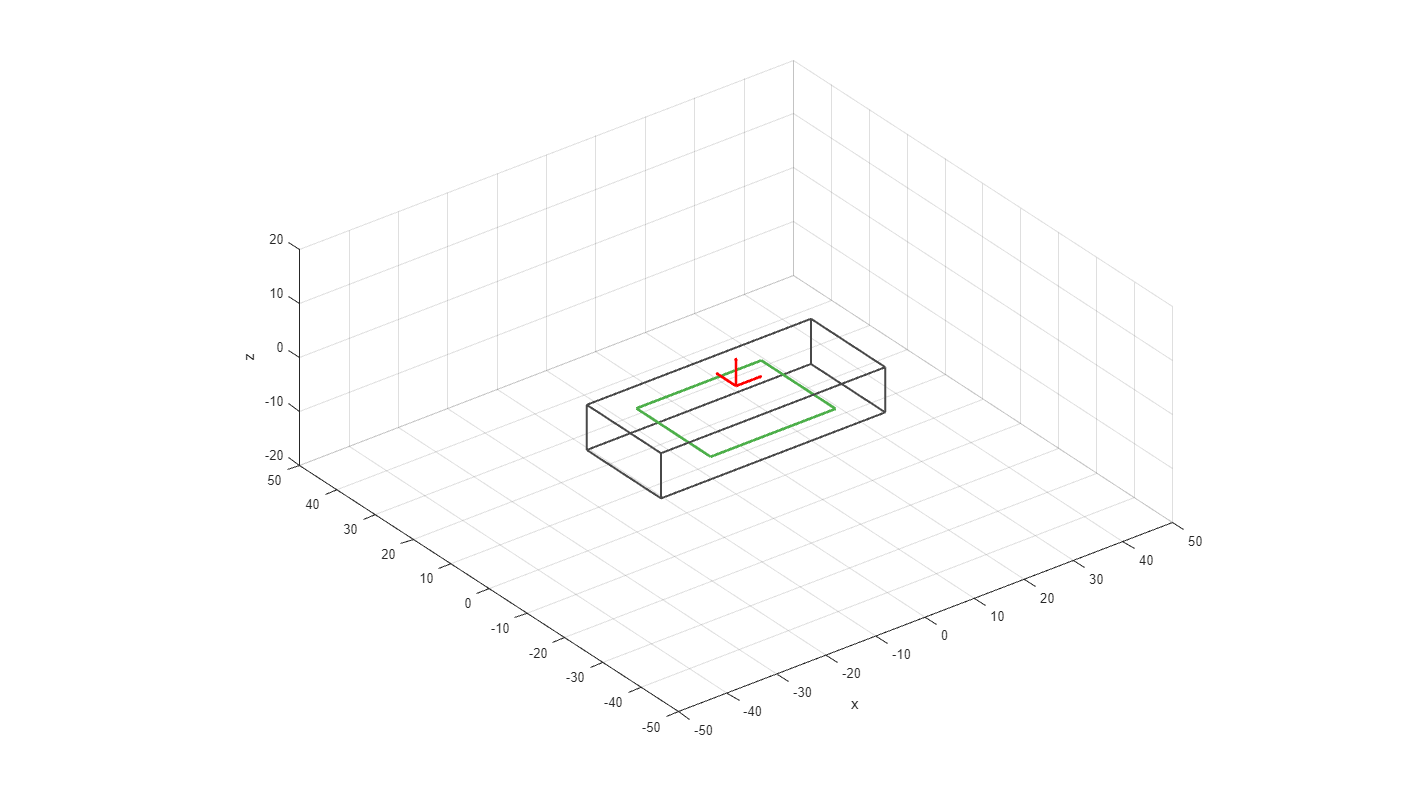

figure('units','pixels','position',[0 0 1920 1080],'Color','w')
% plot the hip bound box %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
quiver3(ht3_b__hip(:, 1), ht3_b__hip(:, 2), ht3_b__hip(:, 3), hip_bound(:, 1), hip_bound(:, 2), hip_bound(:, 3),...
    'LineWidth', 2, 'Color', [77, 175, 74]/255, 'AutoScale', 'off', 'ShowArrowHead', 'off');
% set some props %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hold on; view(-37.5, 30); axis square equal; axis([-50 50 -50 50 -20 20]); xlabel('x'); zlabel('y'); zlabel('z');
% plot the body bound boxes and complete it %%%%%%%%%%%%%%%%%%%
quiver3(ht3_b__bboundT(:, 1), ht3_b__bboundT(:, 2), ht3_b__bboundT(:, 3), bodywoleg_bound(:, 1), bodywoleg_bound(:, 2), bodywoleg_bound(:, 3),...
    'LineWidth', 1.5, 'Color', [72, 72, 72]/255, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % top box
quiver3(ht3_b__bboundB(:, 1), ht3_b__bboundB(:, 2), ht3_b__bboundB(:, 3), bodywoleg_bound(:, 1), bodywoleg_bound(:, 2), bodywoleg_bound(:, 3),...
    'LineWidth', 1.5, 'Color', [72, 72, 72]/255, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % bottom box
quiver3(ht3_b__bboundB(:, 1), ht3_b__bboundB(:, 2), ht3_b__bboundB(:, 3), ht3_b__bboundB2T(:, 1), ht3_b__bboundB2T(:, 2), ht3_b__bboundB2T(:, 3),...
    'LineWidth', 1.5, 'Color', [72, 72, 72]/255, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % connection
% plot the body frame %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
quiver3(zeros(3,1), zeros(3,1), zeros(3,1), [5, 0, 0]', [0, 5, 0]', [0, 0, 5]', 'LineWidth', 2, 'Color', 'r', 'AutoScale', 'off');

### Full SE(3) transformations in body frame

Let's model the legs about the SFB using lift and swing angles inputs-- the positive lift and swing angles are shown in the 3D reconstruction sketch.

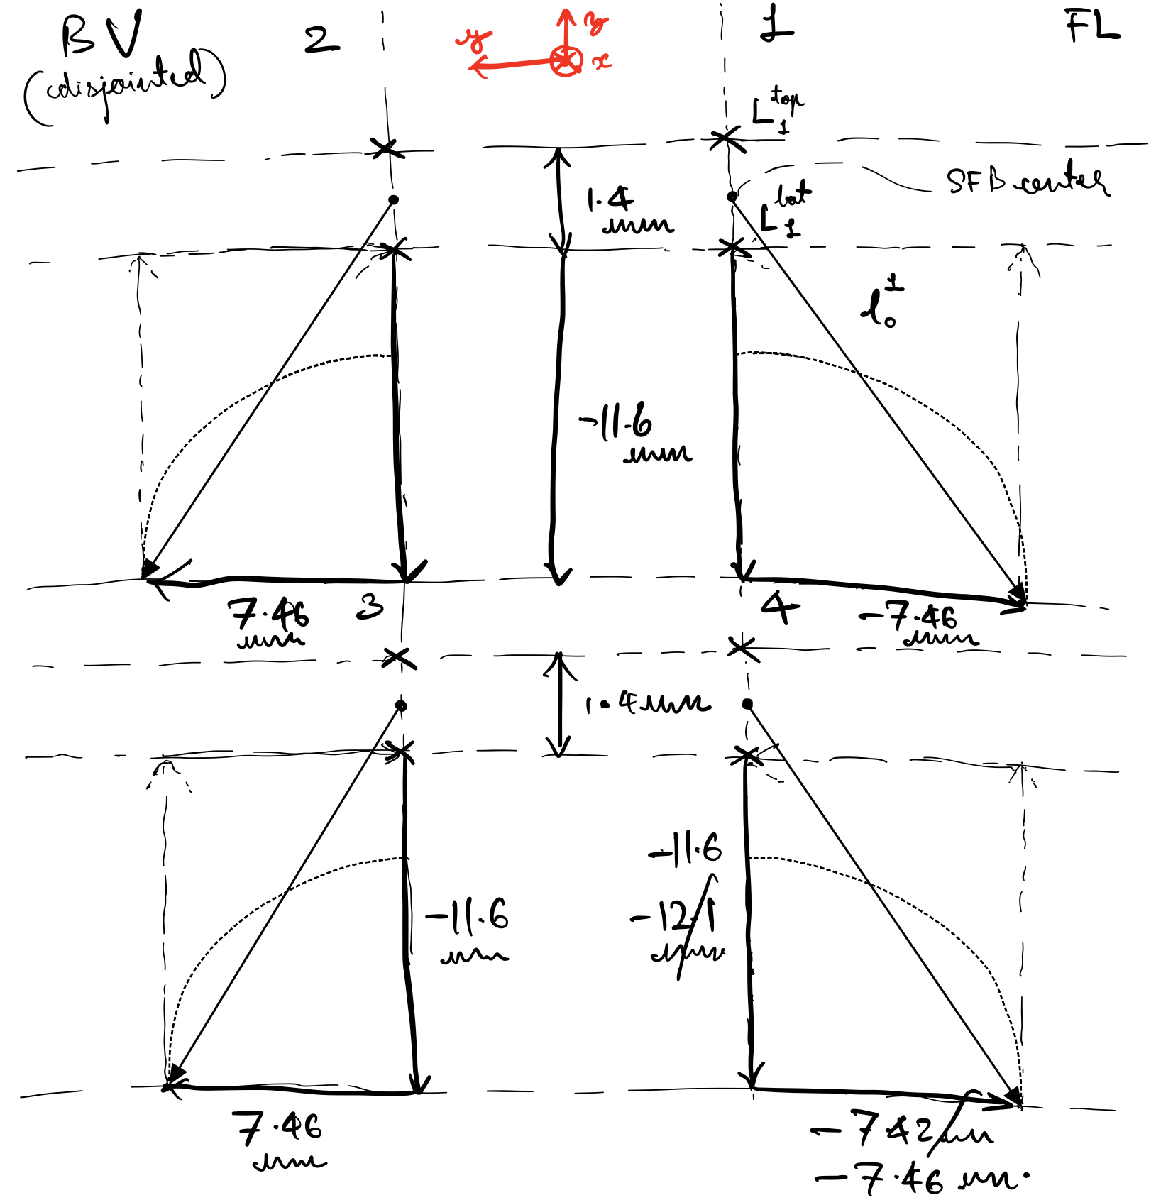

Thus, the leg transformations from the SFB are given by,